clear;
col_tot = 200;
row_tot = 200;
t = 1;


%% 对角化计算态密度
Disorder = 0;
epsilon = 0.05;
H_sparse = Graphene_Armchair_Real_Sparse(row_tot,col_tot,t) ;
% H_sparse = sparse(Lieb_2D_Hamiltonian_Real([0,0,0],1.3,0.7,0.7,row_tot,col_tot));

H_sparse = H_sparse + Disorder * sprand(speye(size(H_sparse)) - 0.5 * speye(size(H_sparse)));
% H_sparse = sprand(col_tot*row_tot,col_tot * row_tot,1e-4);
tic;

%% KPM计算态密度

N_randvec = 20;
N_moments = ceil(1.2*row_tot);
N_points = 2 * N_moments+1;
% N_points = 300;
[H_tilde, a, b] = KPM_scaleHamiltonian(H_sparse);

% Kernel_Jackson = KPM_Kernel(N_moments, 'Jackson');

% Moments = KPM_Moments_Spectrum_test_mex(H_tilde, int32(N_randvec), int32(N_moments));
Moments = KPM_Moments_Spectrum_test(H_tilde, int32(N_randvec), int32(N_moments));

toc;

历时 11.821693 秒。


Moments_Kernel = KPM_Kernel_Correction(Moments, N_moments, 'Jackson');

% omega_dct = linspace(-1+epsilon,1-epsilon,N_points);
% DOS = zeros(1,length(omega_dct));
% parfor ii = 1:length(omega_dct)
%     DOS(ii) = (1/pi ./sqrt(1-omega_dct(ii).^2)) .*(Moments_Kernel*chebyshevT(0:N_moments-1,omega_dct(ii))');
% end

[omega_dct, DOS] = KPM_DCT(Moments_Kernel, N_points);
DOS = sqrt(length(Moments_Kernel)) * DOS;
omega = KPM_rescale(omega_dct, a, b);

% Normalize the DOS
% DOS = DOS / max(DOS,[],'all')*BinMax;

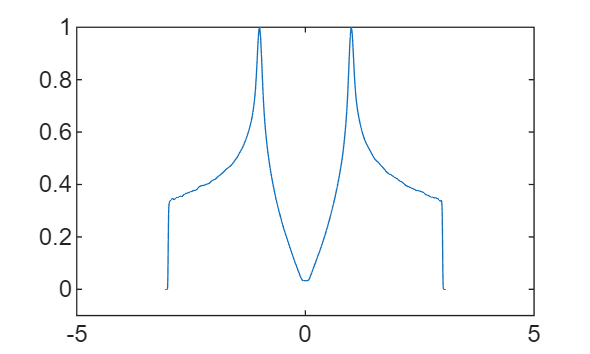


% hold on
plot(omega, DOS/max(DOS,[],'all'))
hold on
% plot(omega, DOS)
axis([-5,5,-1e-1,1])